basePath = 'C:\Users\nsah01\Downloads\VisTexColor40_2023\'

basePath = 'C:\Users\nsah01\Downloads\VisTexColor40_2023\'

imgPath = 'C:\Users\nsah01\Downloads\VisTexColor40_2023\Buildings.0009.01.tif'

imgPath = 'C:\Users\nsah01\Downloads\VisTexColor40_2023\Buildings.0009.01.tif'

nlevels = 3

nlevels = 3

nsubs = 16

nsubs = 16

color = 2

color = 2

[rr,r, rs, ormax,asd] = CBIR_Simple(basePath, nlevels, nsubs,color)

rr =      1     5    16    47     2     2     7    35     6     2    20    53     5    61    54    59     1    19     7   131    63     2   107    11     3    71   146    10    68    35    15   245     1    13    18    23     2    18    31    18     5    19    32    60    13    21     4    17     1     3
     7     1     5    13    14     8     5    14    57     7     6    15    28    89    34    17    15     1     4    11     6    20     8     9    93     9     7    12    35     2     5    25     7     1     2     8     7     3     4     2     6     4     6     8     2     4     2     2     2     1
    22     8     1    16    56    21     3     5    63    21     3    19    30    39     5    28     5     4     1    18    13     4    17     5    28    15    27     6    40     6     2    97    22     3     1    16    23     5     2     5    13    10     7    11     5     5     7     3     7     4
    88    30    34     1   105    83    34     9   188   105    21     2   127   147    36  

r = 76.6504

rs =    38.6719   63.6719   73.0469   74.2188   62.1094   79.2969   78.1250   96.4844   96.4844   60.1562   96.4844   82.4219   94.9219   95.7031   91.7969   98.8281   93.7500   72.2656   94.1406   98.8281   60.5469   49.6094   62.8906   68.7500   87.1094   62.1094   65.2344   64.0625   94.5312   82.8125   83.2031   46.4844   60.9375   63.6719   51.1719   85.1562   99.6094   98.0469   39.0625   99.6094


ormax = 94.8114

asd =     2.7396    3.4076    3.6928    4.3464    2.0647    2.6828    3.7416    4.2015    2.4017    2.8092    4.1394    4.3845    2.6064    3.3457    4.6792    4.4982    4.2158    3.5312    3.2007    2.7177    3.1500    4.1515    2.9530    3.2057    3.6063    2.9947    2.8266    3.0982    3.1810    3.2905    3.4789    2.3437    2.1134    2.2822    2.3228    2.9578    2.0899    2.0104    2.2309    2.2715    2.6135    2.3820    2.5881    2.2034    2.1453    1.9873    1.9037    2.5841    2.8297    2.8535
    2.5068    2.7607    2.9771    2.5454    2.2085    2.6260    2.7305    2.9644    2.1216    2.5732    2.6069    2.6147    2.2959    2.7188    2.5708    2.4116    2.2422    1.8037    1.8853    1.7520    2.3281    2.4922    1.8813    2.0571    2.4487    1.8887    2.0181    2.0146    2.2285    1.9648    2.1250    1.6553    2.7617    2.4888    2.4429    2.8042    2.5454    2.4468    2.5933    2.5352    2.5928    2.5244    2.4766    2.5850    2.5122    2.4624    2.7451    2.6836    3.1592   

imgVector = wavefeat_asd_color(imgPath, nlevels)

imgVector =     2.8064
    3.4180
    2.8948
    3.8818
    0.4886
    0.1768
    1.4022
    0.5994
    0.9966
    0.4001


database_files = dir(fullfile(basePath, '*.tif'))

database_files = 640×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


nimages = length(database_files);

distarray = zeros(nimages,1)

distarray =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



for i=1:nimages
	distarray(i) = sum (( abs ( asd (:,i) - imgVector)) .^2, 1);
end

[diff, index] = sort(distarray)

diff =          0
    0.1012
    0.2421
    0.2494
    0.3242
    0.7190
    0.7958
    0.9042
    0.9048
    0.9528


index =    113
   117
   121
   114
   122
   118
   115
   123
   116
   126


Image: Buildings.0009.01.tif
Image: Buildings.0009.05.tif
Image: Buildings.0009.09.tif
Image: Buildings.0009.02.tif
Image: Buildings.0009.10.tif


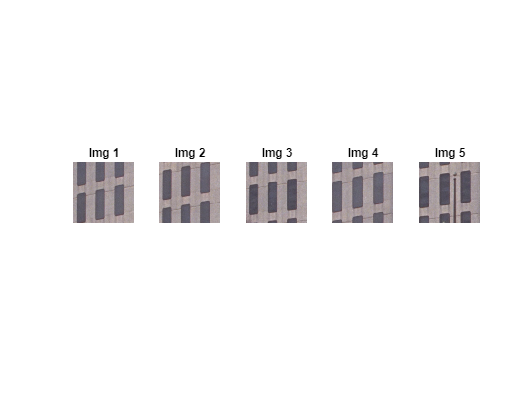

showImages(index,basePath,database_files,5)